# Plot sound spectra

In English, vowels can be thought of as steady-state sounds whose frequency content remains constant over time. In this script, we will generate the synthetic vowel sounds used in the project and plot their spectra to highlight the different formant locations that define vowel sound identity. We will then plot the spectra of a single vowel when modifying orthogonal features such as fundamental frequency and level to illustrate how these change the sound spectra but preserve formant features that convey identity.

% Define the formant positions for each vowel
tags = {'/u/','/\epsilon/','/a/','/i/'};            

formants = [ 460        1105        2857        4205;   % /u/
             730        2058        2857        4205;   % /e/
             936        1551        2975        4263;   % /a/
             437        2761        2975        4263];  % /i/
 
% Define the sample rate with which to generate sounds (e.g. 50 kHz)
fs = 50000;

% Sound duration in seconds
duration = 0.25;

% Plot settings
FontName = 'Arial';
FontSize = 8;

First we'll compare the spectra of each vowel synthesized with the same level and fundamental frequency.

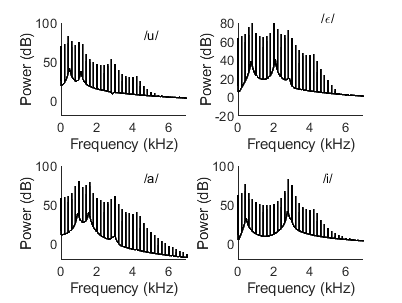

% Draw figure
figure( 'color','w',...
        'units','centimeters',...
        'position',[5 5 8.5 6.4])

F0 = 200;

for i = 1 : size(formants, 1)   % for each vowel type (/a/, /i/ ...)
    
    subplot(2,2,i);        
    hold on    
 
    vowel = newMakeVowel2009( duration, fs, F0,...
        formants(i,1),...
        formants(i,2),...
        formants(i,3),...
        formants(i,4));
    
    NFFT  = length(vowel);
    Y     = fft(vowel,NFFT);
    f     = fs/2 * linspace(0,1,NFFT/2);    
    Yf    = 2 * abs(Y(1:NFFT/2));
    yf    = 20 * log10(Yf);
    
    plot(f, yf, 'color', 'k','lineWidth',1)
       
    text(5e3, 85, tags{i},...    % Text label
            'FontName', FontName,...
            'FontSize', FontSize,...
            'HorizontalAlignment', 'Center')
    
    set(gca, 'xtick', 0 : 2e3 : 6e3,...
             'xticklabel', {'0','2','4','6'},...
             'FontName', FontName,...
             'FontSize', FontSize)    
    
    xlim([0 7e3])
    
    yLims = get(gca,'ylim');
    ylim([-20 yLims(2)])
    
    xlabel('Frequency (kHz)')
    ylabel('Power (dB)')
end

Plot the spectra of a vowel that varies in fundamental frequency; the spectra are shown with a vertical offset as appears in Figure 1 in the paper.

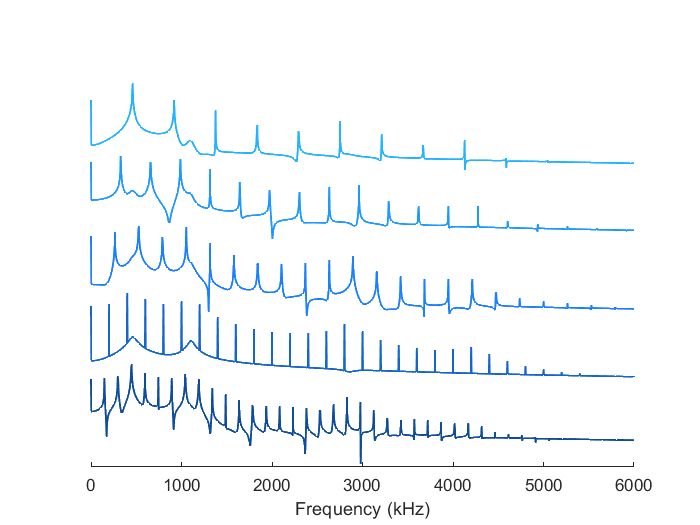

figure
hold on

color = [0.1 0.5 1];
myF0  = [149 200 263 330 459];
n = numel(myF0);

formant_idx = 1;    % Index for vowel (e.g. /u/)

for i = 1 : n
    
    vowel = newMakeVowel2009( duration, fs, myF0(i),...
       formants(formant_idx,1),...
       formants(formant_idx,2),...
       formants(formant_idx,3),...
       formants(formant_idx,4));

    NFFT  = length(vowel);
    Y     = fft(vowel,NFFT);
    f     = fs/2 * linspace(0,1,NFFT/2);    
    Yf    = 2 * abs(Y(1:NFFT/2));
    yf    = 20 * log10(Yf);
    
    
    color_i = color .* (0.4+(i/n));
    color_i(color_i>1) = 1;
    
    cIdx(i,:) = color_i;
    plot(f, yf+(i*65), 'color', color_i,'lineWidth',1,'tag',num2str(myF0(i)))
    
end

xlim([0 6e3])
xlabel('Frequency (kHz)')

set(gca,'ycolor','none')

Plot the spectra of a vowel that varies in sound level; the spectra are shown with a vertical offset as appears in Figure 1 in the paper.

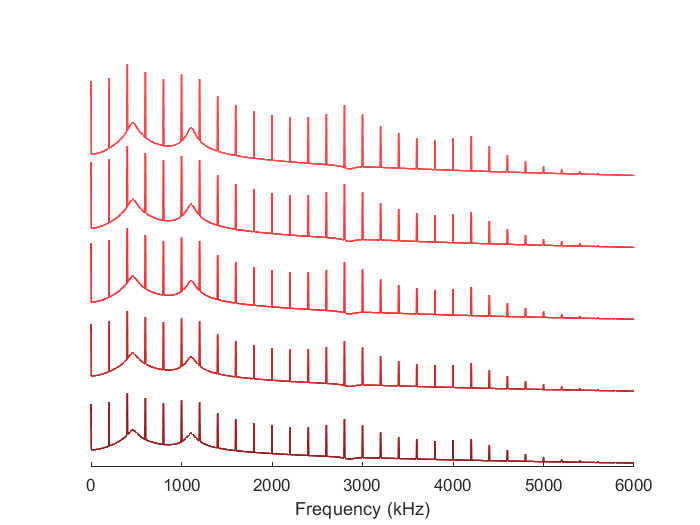

figure
hold on

color = [1 0.2 0.2];
attn  = 50 : 7.5 : 80;
n = numel(attn);

F0 = 200;   % Constant fundamental frequency
formant_idx = 1;    % Index for vowel (e.g. /u/)

for i = 1 : n
    
    vowel = newMakeVowel2009( duration, fs, F0,...
       formants(formant_idx,1),...
       formants(formant_idx,2),...
       formants(formant_idx,3),...
       formants(formant_idx,4));
        
    NFFT  = length(vowel);
    Y     = fft(vowel,NFFT);
    f     = fs/2 * linspace(0,1,NFFT/2);    
    Yf    = 2 * abs(Y(1:NFFT/2));
    yf    = 20 * log10(Yf);
    yf    = yf .* (attn(i)/20);
    
    color_i = color .* (0.4+(i/n));
    color_i(color_i>1) = 1;
    
    cIdx(i,:) = color_i;
    plot(f, yf+(i*200), 'color', color_i,'lineWidth',1,'tag',num2str(attn(i)))  
end

xlim([0 6e3])
xlabel('Frequency (kHz)')
set(gca,'ycolor','none')